# Problem 5

## Author: Tomoki Koike

#### Using a 4096 FFT, plot the function  


$$g\left(t\right)\;=2+7\mathrm{cos}\left(\frac{6\pi t}{10}\right)-5\mathrm{cos}\left(\frac{8\pi t}{10}\right)+6\mathrm{sin}\left(\frac{10\pi t}{10}\right)\;\;\;\;\;L=\left\lbrack 0\;\;10\right\rbrack$$


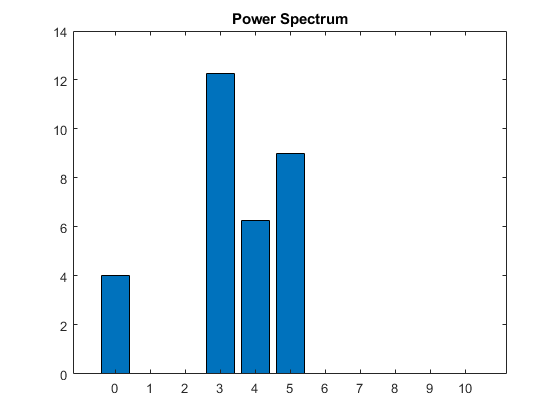

clear all 
close all 
clc

% Defining the span of time variable, t
t = (0:2^12-1)*10/2^12;
% Defining the function subjected to FFT
g = 2 + 7*cos(6*pi*t/10) - 5*cos(8*pi*t/10) + 6*sin(10*pi*t/10);
% FFT 
a = ifft(g);

% Plot the power spectrum
figure(1)
bar((0:10), abs(a(1:11)).^2)
title('Power Spectrum')

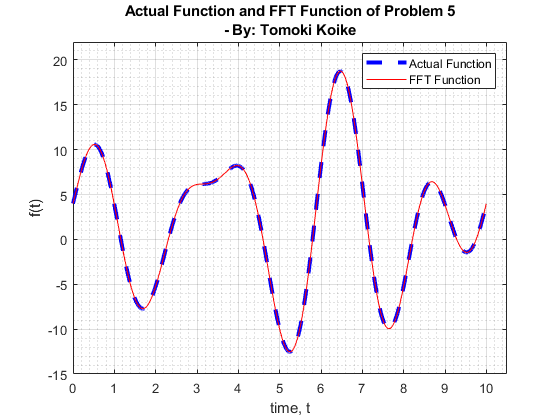


% From the power spectrum we can tell that the only frequencies that we 
% have to take into account are a0=a(1), a3=a(4), a4=a(5), and a5=a(6)
% Partial Fourier Series Using Loop
part = a(1);
for k = 4:6
    part = part + 2*real(a(k)).*cos((k-1)*pi*t/5) + 2*imag(a(k)).*sin((k-1)*pi*t/5);
end

% PLotting 
figure(2)
plot(t, g, '--b', 'LineWidth', 3.0)
xlabel('time, t')
ylabel('f(t)')
title({'Actual Function and FFT Function of Problem 5', ['- By' ...
    ': Tomoki Koike']})
grid on
grid minor
box on
hold on 
plot(t, part, 'r')
hold off
xlim([0 10.5])
ylim([-15 22])
legend('Actual Function', 'FFT Function')

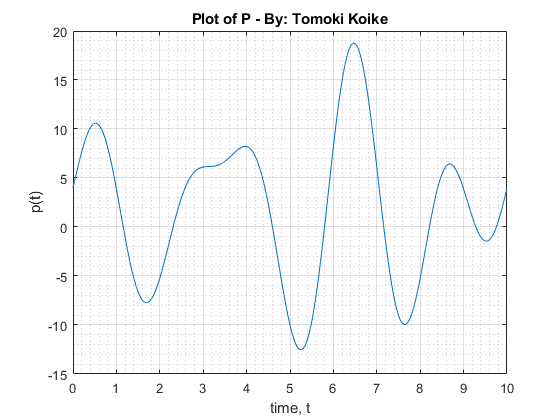


% Then consider the following command
p = real(fft([2;0;0;7;-5],4096)) + imag(fft([0;0;0;0;0;-6], 4096));
% PLotting 
figure(3)
plot(t, p)
xlabel('time, t')
ylabel('p(t)')
title('Plot of P - By: Tomoki Koike')
grid on
grid minor
box on

## Analysis

The code p = real(fft([2;0;0;7;-5],4096)) + imag(fft([0;0;0;0;0;-6], 4096));

is exactly the same as the function g(t) that was transformed into a Fourier Series in the 

previous steps. 